# Exercise 1: Simulink Introduction

## A) Simulation of a Bouncing Ball

A bouncing ball model is an example of a hybrid dynamic system. A hybrid dynamic system is a system that involves both continuous dynamics and discrete transitions where the system dynamics can change and the state values can jump. The continuous dynamics of a bouncing ball are given by these equations:

(1) $\frac{\textrm{dv}}{\;\textrm{dt}\;}=-g\;,$

(2) $\frac{\textrm{dx}}{\textrm{dt}}=v$,

where $g\;$is the acceleration due to gravity, $x\left(t\right)$ is the position of the ball, and $v\left(t\right)$ is the velocity. The system has two continuous states: the position $x$ and the velocity $v$.

The hybrid system aspect of the model originates from the modeling of a collision of the ball with the ground. If one assumes a partially elastic collision with the ground, then the velocity before the collision, $v^-$, and velocity after the collision, $v^+$, can be related by the coefficient of restitution of the ball, $\kappa$, as follows:


$$v^+ =-\kappa v^- ,\;x=0$$


The bouncing ball therefore displays a jump in a continuous state (velocity) at the transition condition, $x=0$. The image shows a ball throw up with a velocity of 0 m/s from a height of 25 m.

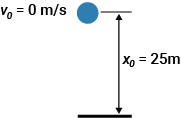

In the following steps we are going to familiarize ourselfs with the Simulink Library Browser and some of its elements by modelling a bouncing ball using two integrator blocks. 

The first integrator we will use describes the velocity equation (1). Open the BouncingBall.slx file and search for "Integrator" in the Library Browser of the "Simulation" menu. Drag in the element onto the blank canvas, double click on it and copy the following settings:

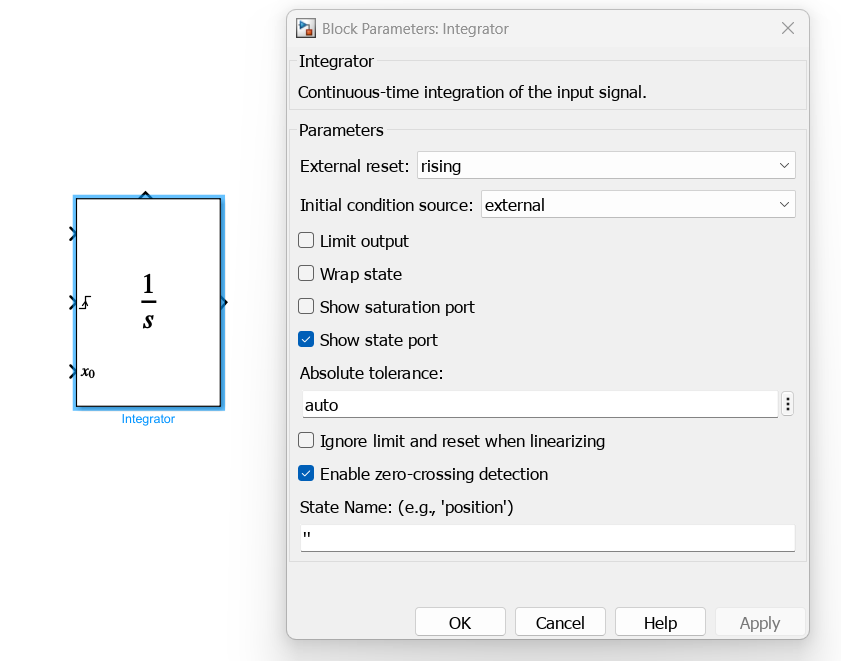

Next we add the following blocks from the Library Browser: Initial Condition, Constant and Gain. After connecting them in the right place it should look like this: 

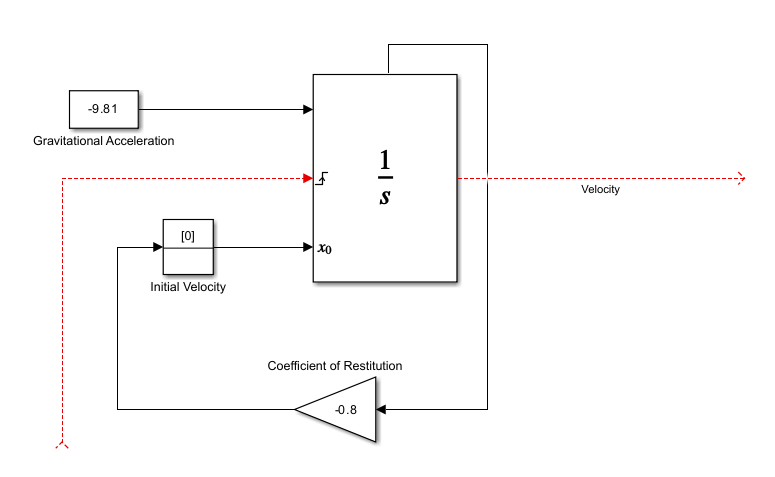

We will repeat a similar process for the position equation and connect everything together into one system with two integrators. Make sure to copy the following settings into the second integrator as we have to set saturation limits for the ball position:

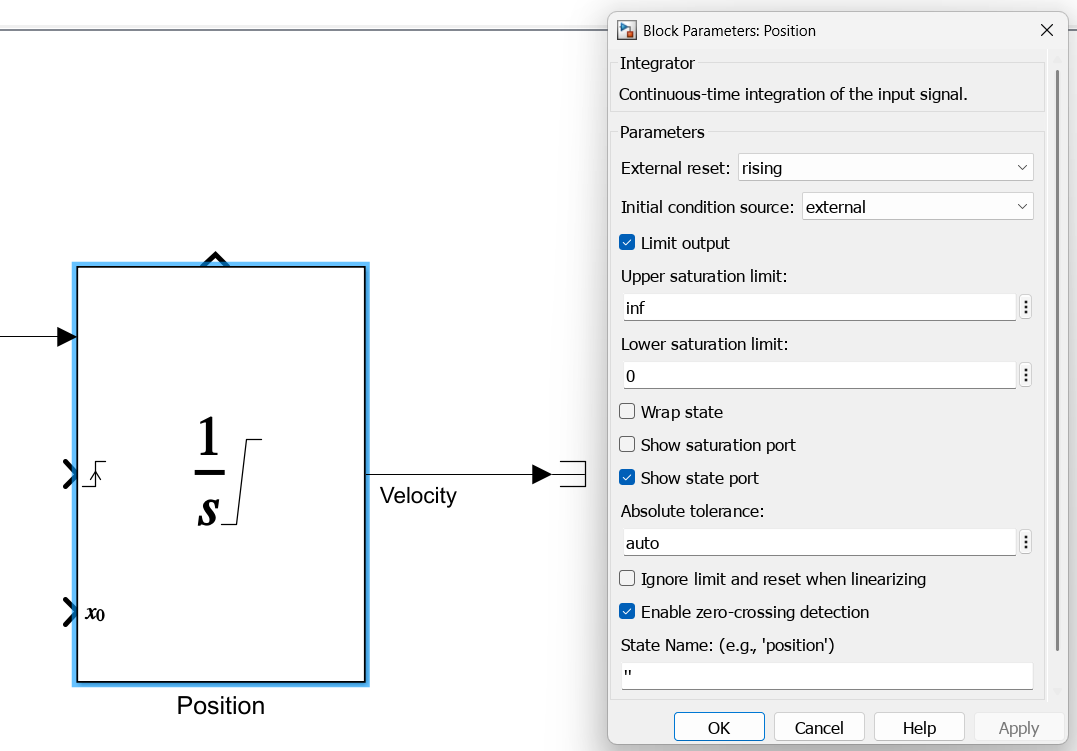

After adding additional CompareToZero, Terminator and Ground blocks to the system it should look like the picture below. To add Scopes to the system right click on the velocity connection and select "Connect To Viewer" then "Simulink" and finally "Scope". Repeat this for the positon too.

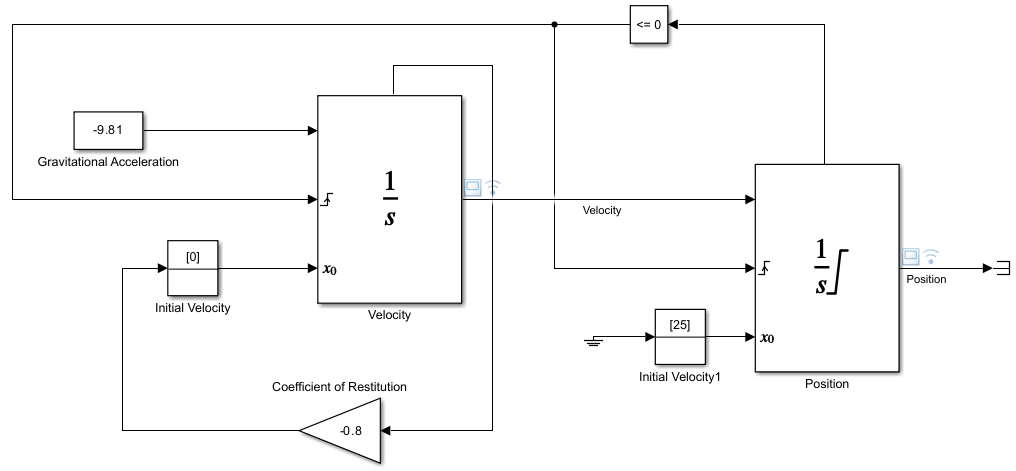

To observe the Zeno behavior of the system, modify solver configuration parameters.

- To open the Configuration Parameters dialog box, on the **Modeling** tab, under **Setup**, click **Model Settings**.

- Select the **Solver** pane.

- Set the **Stop time** to `25`.

- Click the arrow next to **Solver details** to view additional solver parameters.

- Under **Zero-crossing options**, set **Algorithm** to `Nonadaptive`.

Run the simulation and look at the scopes. What do you see? How does this system work? Show your plots to the TA and answer the questions.

In the next step you should use the Second-Order Integrator Block and try to figure out how to get the same scope plots that you received using two First-Order Integrators. Use the settings from the picture below. TIPP: Use a "Memory" block from the Library Browser. Think about why we need this element (check out: [https://ch.mathworks.com/help/simulink/ug/algebraic-loops.html](https://ch.mathworks.com/help/simulink/ug/algebraic-loops.html)).

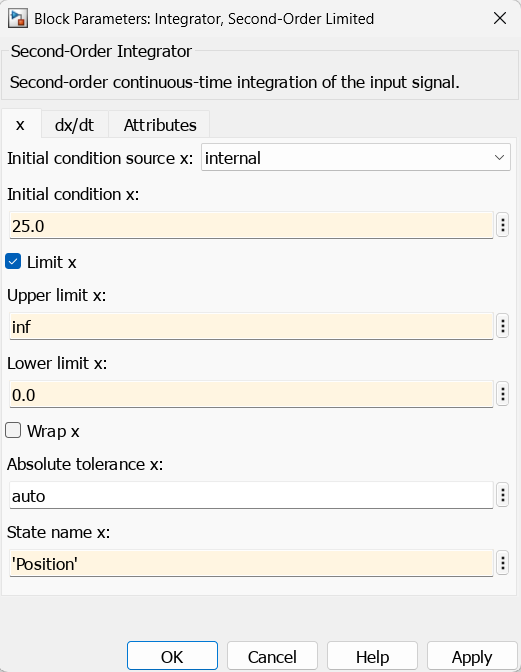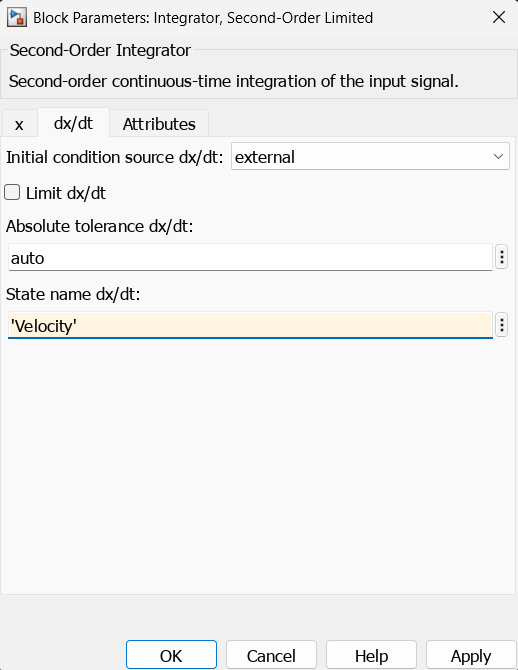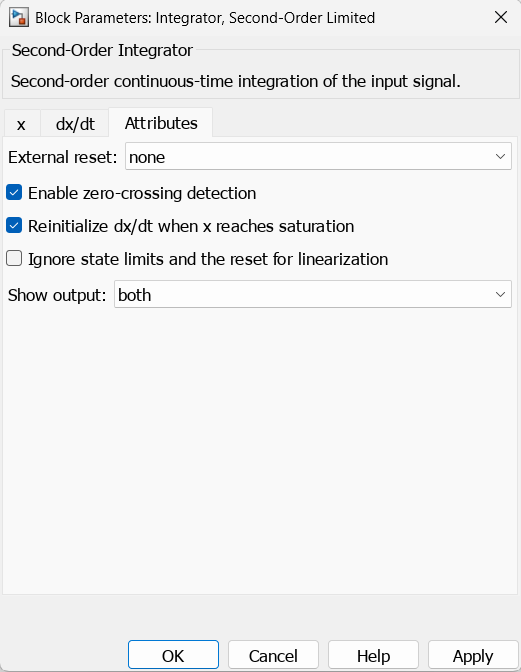

## B) Simulating a Motor Electronic Speed Controller (ESC)

To understand what a Electronic Speed Controller is, we have to look at the layout of quadrotor drone:

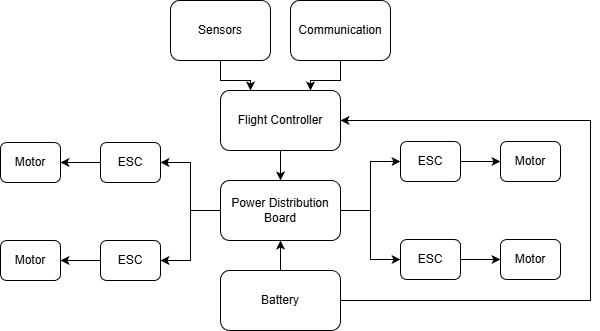

The flight controller is the main "brain" of the drone. It receives data from sensors and some peripheral which is controlled by the user (usually Radio Links via Laptop or RC Controllers) and makes the internal calculations to keep the drone flying stably. The result of these calculations then has to be transfered to the four motors. Here we first have the "Power Distribution Board" that takes the signals from the flight controller and power from the battery and supplies both power and instructions to the ESCs. The flight controller sends signals in form of "Pulse-Width-Modulation" commands (see also: [https://en.wikipedia.org/wiki/Pulse-width_modulation](https://en.wikipedia.org/wiki/Pulse-width_modulation) more modern protocols also include DShot). These assign a certain duty cycle percentage to a motor speed that has to be matched. The ESC interprets this command as a desired motor speed and converts it into a high-frequency switching signal that controls how much electrical energy is delivered to the motor from the battery. By modulating the applied voltage (and current) through this switching, the ESC regulates the motor torque and thus its rotational speed, allowing the drone to generate the precise thrust needed for stable flight. 

In the following exercise we are going to simulate the speed controlling behaviour of the ESC using a simple Simulink model with real parameters of the brushed coreless DC-motors that will be used in the practical sessions. To start our simulation we need to run the following code to load the variables into our workspace.

%% Motor parameters (from datasheet)
motor.Kv_rpm_per_V = 13000;
motor.Vbatt = 3.4;          % Battery voltage [V]
motor.maxRPM = motor.Kv_rpm_per_V * motor.Vbatt;

%% ESC limits
esc.maxVoltage = motor.Vbatt;

%% Simulation parameters
simParams.Ts = 0.001;             % Sample time [s]
simParams.stopTime = 2;           % Simulation length [s]

%% P Controller
Kp = 0.002;

efvierjbgpqe9rurhp9q#

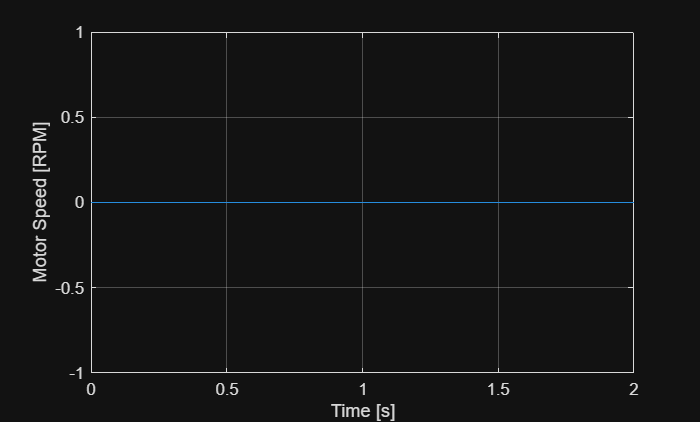

%% Test input
rpm_cmd = 0.6 * motor.maxRPM;

simIn = Simulink.SimulationInput('MotorESC');
simIn = simIn.setVariable('rpm_ref', rpm_cmd);
simIn = simIn.setVariable('Kp', Kp);

out = sim(simIn);

rpm_out = out.logsout.getElement('rpm_actual').Values;

plot(rpm_out.Time, rpm_out.Data)
xlabel('Time [s]')
ylabel('Motor Speed [RPM]')
grid on